# 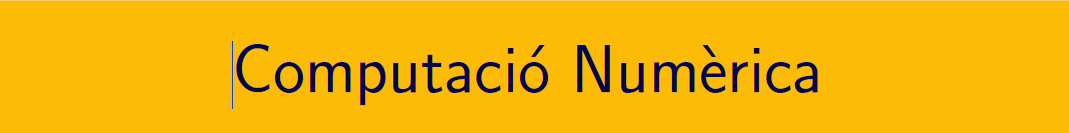

`===================================================================================`

# `Pràctica 14. Equacions diferencials ordinàries (IV).`

`Document preparat per M. Àngela Grau Gotés - 29 de maig de 2023`

## `Sistemes d'equacions diferencials de primer ordre`

## `Exercici  `$y^{\prime\prime}(t)-2y^{\prime}(t)+2y(t)=e^{2t}\sin t\,,\quad y(0)=-0.4,\  y^{\prime}(0)=-0.6,\quad 0\leq t\leq 1\,.$

`Reducció a un sistema d'equacions de primer ordre`

`El canvi seria, `$u_1(t) = y(t)\,,\quad u_2(t) = y{^\prime}(t)$` i el sistema de primer ordre és `


$$	\left\lbrace \begin{array}{rcl}
			u_1^{\prime}(t)&=&u_2(t)\,, 			\\  u_2^{\prime}(t)&=&e^{2t}\sin t-2u_1(t)+2u_2(t)\,, \\
u_1(0) &=& -0.4\,,\\
u_2(0) &=& -0.6\,.
\end{array}\right. $$


`Solució analítica`

clearvars
syms y(t) z(t)
eqns = [diff(y,t) == z, diff(z,t) == exp(2*t)*sin(t)-2*z+2*y];
conds = [y(0) == -0.4, z(0)==-0.6];
[ySol(t),zSol(t)] = dsolve(eqns,conds);

`La solució es pot respresentar a l'interval [0,1]`

Y(t) = simplify(ySol(t)), Z(t) = simplify(zSol(t))

$$Y(t) = \begin{array}{l} {\mathrm{e}}^{-t\,\left(\sqrt{3}+1\right)}\,\left(\frac{2\,\sqrt{3}\,\left(7\,\sqrt{3}+9\right)}{15\,\sigma_{1}}+\frac{{\mathrm{e}}^{3\,t+\sqrt{3}\,t}\,\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)\,\left(\cos\left(t\right)-\sin\left(t\right)\,\left(\sqrt{3}+3\right)\right)}{{\left(\sqrt{3}+3\right)}^{2}+1}\right)\,\left(\frac{\sqrt{3}}{2}-\frac{1}{2}\right)+{\mathrm{e}}^{t\,\left(\sqrt{3}-1\right)}\,\left(\frac{\sqrt{3}}{2}+\frac{1}{2}\right)\,\left(\frac{2\,\left(261\,\sqrt{3}+535\right)}{5\,\left(6\,\sqrt{3}-13\right)\,{\sigma_{1}}^{2}}-\frac{\sqrt{3}\,{\mathrm{e}}^{3\,t-\sqrt{3}\,t}\,\left(\cos\left(t\right)+\sin\left(t\right)\,\left(\sqrt{3}-3\right)\right)\,\left(\sqrt{3}-1\right)}{6\,\left({\left(\sqrt{3}-3\right)}^{2}+1\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=6\,\sqrt{3}+13 \end{array}$$

$$Z(t) = \begin{array}{l} {\mathrm{e}}^{t\,\left(\sqrt{3}-1\right)}\,\left(\frac{2\,\left(261\,\sqrt{3}+535\right)}{5\,\left(6\,\sqrt{3}-13\right)\,{\sigma_{1}}^{2}}-\frac{\sqrt{3}\,{\mathrm{e}}^{3\,t-\sqrt{3}\,t}\,\left(\cos\left(t\right)+\sin\left(t\right)\,\left(\sqrt{3}-3\right)\right)\,\left(\sqrt{3}-1\right)}{6\,\left({\left(\sqrt{3}-3\right)}^{2}+1\right)}\right)-{\mathrm{e}}^{-t\,\left(\sqrt{3}+1\right)}\,\left(\frac{2\,\sqrt{3}\,\left(7\,\sqrt{3}+9\right)}{15\,\sigma_{1}}+\frac{{\mathrm{e}}^{3\,t+\sqrt{3}\,t}\,\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)\,\left(\cos\left(t\right)-\sin\left(t\right)\,\left(\sqrt{3}+3\right)\right)}{{\left(\sqrt{3}+3\right)}^{2}+1}\right)\\ \mathrm{where}\\ \sigma_{1}=6\,\sqrt{3}+13 \end{array}$$

## `Solucions aproximades numèricament O(h)`

- `Mètode Euler (sistemes equacions)`

[t,YE] = EulerV(@edos,0,1,0.05,[-0.4; -0.6])

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


YE =    -0.4000   -0.6000
   -0.4300   -0.5800
   -0.4590   -0.5622
   -0.4871   -0.5458
   -0.5144   -0.5299
   -0.5409   -0.5135
   -0.5666   -0.4958
   -0.5914   -0.4760
   -0.6152   -0.4530
   -0.6378   -0.4259


E = norm(abs(double(vpa(Y(t),20))'-YE(:,1)),'inf')

E = 0.0446

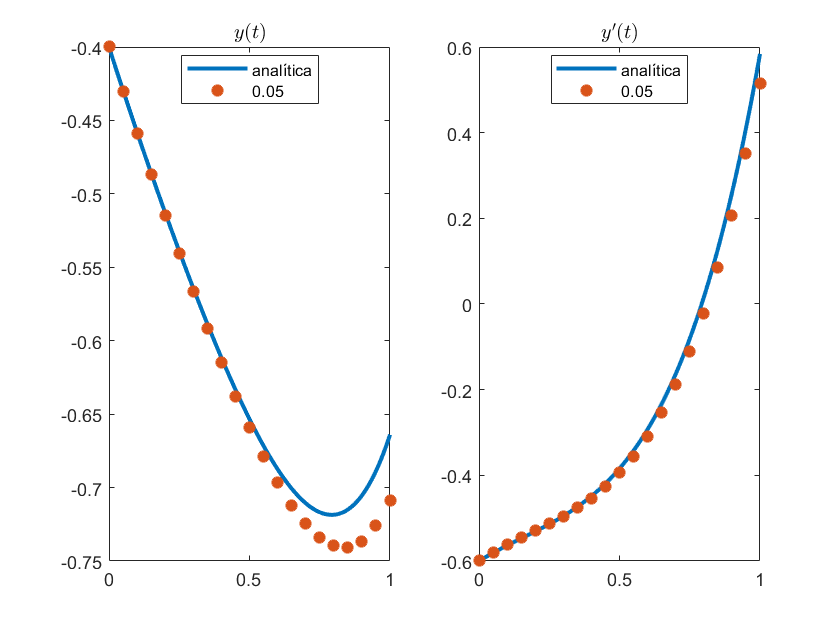


% Gràfics
u = linspace(0, 1, 500);
clf,figure(1)
subplot(121),plot(u,Y(u),t,YE(:,1),'*','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(u,Z(u),t,YE(:,2),'*','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')

## `Solucions aproximades numèricament O(h^2)`

- `Mètode ode23`

[t,y] = ode23(@edos,[0 1],[-0.4; -0.6])

t =          0
    0.0533
    0.1533
    0.2533
    0.3533
    0.4533
    0.5533
    0.6527
    0.7403
    0.7930


y =    -0.4000   -0.6000
   -0.4315   -0.5799
   -0.4878   -0.5464
   -0.5407   -0.5127
   -0.5901   -0.4721
   -0.6347   -0.4171
   -0.6727   -0.3394
   -0.7013   -0.2300
   -0.7159   -0.0983
   -0.7185    0.0010


E = norm(abs(double(vpa(Y(t),20))-y(:,1)),'inf')

E = 2.5381e-05

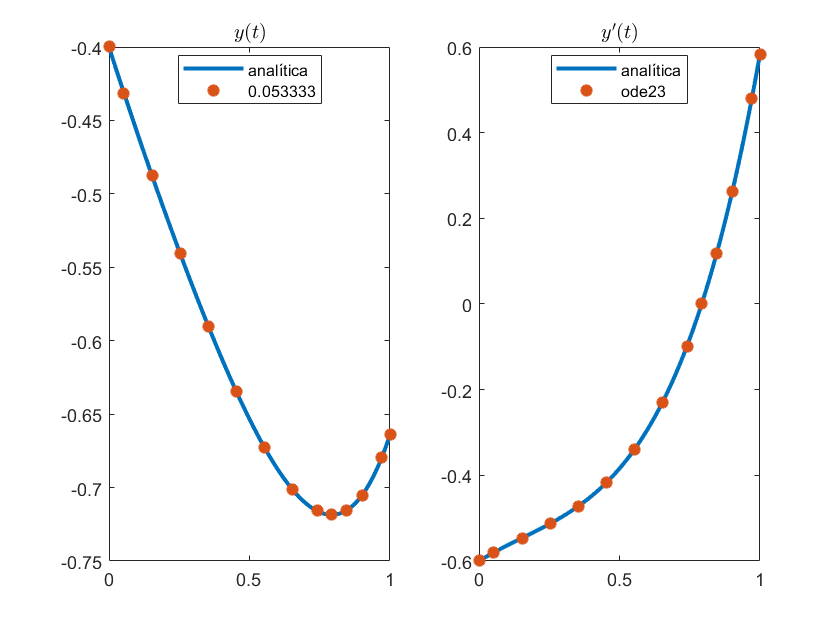


% Gràfics
u = linspace(0,1);
clf,figure(1)
subplot(121),plot(u,Y(u),t,y(:,1),'*','LineWidth',2)
title('$y(t)$','Interpreter','latex')
legend('analítica',num2str(t(2)-t(1)),'Location','best')
subplot(122),plot(u,Z(u),t,y(:,2),'*','LineWidth',2)
title('$y^\prime(t)$','Interpreter','latex')
legend('analítica','ode23','Location','best')

function dydt = edos(t,y)
% 
    dydt = [y(2); 2*y(1)-2*y(2)+exp(2*t)*sin(t)];
end
%---------------------------------------
function [t, w ] = EulerV( f,a,b,h,alpha )
% Mètode d'Euler
% f una funcion @algo que retorna un vector columna [y1; y2; ...]
t=[a:h:b];
N=length(t);
w(1,:)=alpha;
    for i=1:N-1
        w(i+1,:)=w(i,:)+h*f(t(i),w(i,:))';
    end
end
%%%%